# Limits and Derivatives, Ordinary Differential Equation with MATLAB

## Part 1: Limit Section

### Q1: Calculate $\underset{x\to 0}{\mathrm{lim}} \frac{\mathrm{sin}\;4x}{x}$

syms x;
y1 = sin(4 * x) / x;
sol1 = limit(y1, 0)

$$sol1 = 4$$

#### Limiting value of the current function at 0 is 4.

### Q2: Find $\underset{x\to 2}{\mathrm{lim}} \frac{x-2}{|x-2|}\;\ldotp$ Does it exist?

y2 = (x - 2) / abs(x - 2);
sol2 = limit(y2, 2)

$$sol2 = \mathrm{NaN}$$

#### Here, Nan defines 'Not a Number'. Hence, the limit does not exist at point 2.

### Q3: Compute $\underset{\theta \to \frac{\pi }{2}}{\mathrm{lim}} \frac{\mathrm{cos}\;\theta }{1+\mathrm{sin}\;\theta }$.

y3 = cos(x) / (1 + sin(x));
sol3 = limit(y3, pi/2)

$$sol3 = 0$$

#### Limiting value of the current function at $\frac{\pi }{2}$ is 0.

### Q4: Find the asymptotes of $\frac{x}{x^2 -3x}$ and plot them as dashed line with the function.

Finding the vertical and horizontal asymptotes for the given function $f\left(x\right)-\frac{x}{\;x^2 -3x}$

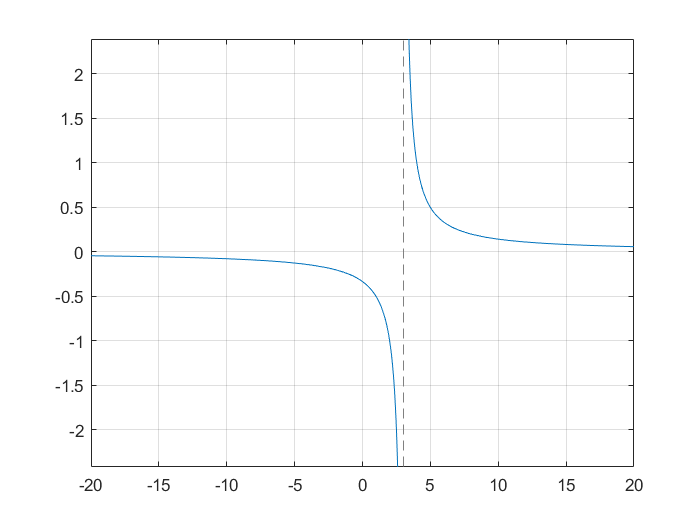

f = @(x) x./(x.^2 - 3*x);
figure(1);
fplot(f, [-20 20])
hold on
grid on
hold off

% finding the vertical asymptote
fprintf('Vertical Asymptotes: ')

Vertical Asymptotes: 

denominator = @(x) x.^2 - 3*x;
v_asymptotes = solve(denominator(x)==0, x)

$$v\_asymptotes = \left(\begin{array}{c} 0\\ 3 \end{array}\right)$$

% finding the horizontal asymptote
fprintf('Horizontal Asymtotes: ')

Horizontal Asymtotes: 

h_asymptote_inf = limit(f(x), x, inf)

$$h\_asymptote\_inf = 0$$

h_asymptote_ninf = limit(f(x), x, -inf)

$$h\_asymptote\_ninf = 0$$

#### The output shows that the vertical asymptotes, which is at x = 0 and x = 3, and the horizontal asymptote, which is at y = 0.

## Part 2: Derivative Section

### Q1: Consider the function $f\left(x\right)=\frac{1}{3x^2 +1}$.

###     (a) What are the first and second derivative?

###     (b) What are the critical points of the functions?

###     (c) What is ${f^{\prime } }^{\prime }$ evaluated at these critical points?

###     (d) Are there any local maxima or minima? Plot the function and show them on the graph.

#### 
$${\mathrm{Sol}}^n :$$


#### (a) 

syms x;
f = 1 / (3*x^2 + 1);
first = diff(f)

$$first = -\frac{6\,x}{{\left(3\,x^{2}+1\right)}^{2}}$$

second = diff(f, 2)

$$second = \frac{72\,x^{2}}{{\left(3\,x^{2}+1\right)}^{3}}-\frac{6}{{\left(3\,x^{2}+1\right)}^{2}}$$

#### Here the first and the second derivatives are shown respecfully.

#### (b) 

cri_points = solve(first == 0, x);
fprintf('The critical point: ');

The critical point: 

disp(cri_points)

$$0$$

den = diff(3*x^3 + 1);
undefined_pts = solve(den == 0, x)

$$undefined\_pts = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

#### The critical point of the function is at x = 0, and there are no undefined points.

#### (c) 

pts = subs(second, x, cri_points);
fprintf('Second derivative at critical point: ');

Second derivative at critical point: 

disp(pts)

$$-6$$

#### The value of second derivative at the critical point is $-6$.

#### (d) 

There is a local minimum for the function $f\left(x\right)=\frac{1}{3x^2 +1}$ at the critical point x = 0. 

To determine the local minima or maxima we need to observe the behavior of the function around the critical points. By using the second derivative of the function, the nature of the critical point is determind. From (c), we can see the value of second derivative at critical point is negative. This indicates the function has a local minimum at $x=0\ldotp$

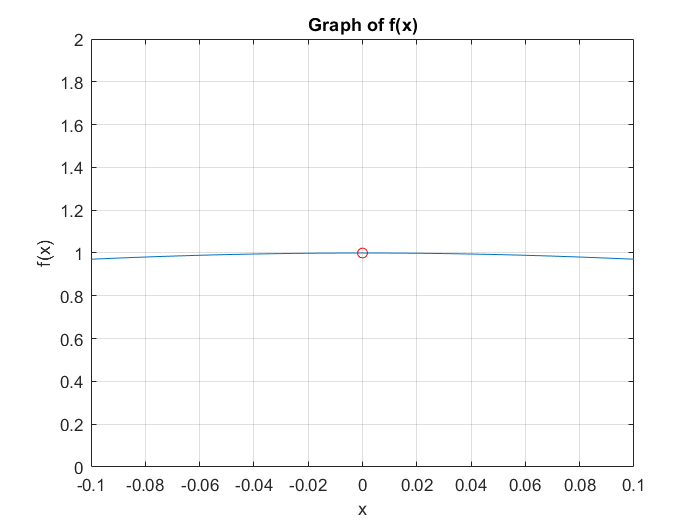

x = linspace(-1, 1, 500);
fx = @(x) 1 ./ (3*x.^2 + 1); % defining function
y = fx(x);
plot(x, y)
grid on
hold on
plot(0, fx(0), 'ro')
xlim([-0.1 0.1])
ylim([0 2])
title('Graph of f(x)')
xlabel('x')
ylabel('f(x)')
hold off

## Part 3: Differential Equations

### Q1: Find the solution in the system

###             
$$\begin{array}{l}
{x_1 }^{\prime } =2x_1 x_2 \\
{x_2 }^{\prime } =-x_1^2 \\
x_1 \left(0\right)=x_2 \left(0\right)=0
\end{array}$$


#### 
$${\mathrm{Sol}}^n :\;$$


The solution for the system is given below: 

% Define the system of ODEs
% x1' = -2*x1 * x2
% x2' = -x2^2
f = @(t, x) [-2*x(1) * x(2); -x(2)^2];

% the initial conditions
x0 = [0 ; 0];

% the time span
tspan = [0, 10];

% solve
[t, x] = ode45(f, tspan, x0);
m = [t,x];
disp(m)

         0         0         0
    0.2500         0         0
    0.5000         0         0
    0.7500         0         0
    1.0000         0         0
    1.2500         0         0
    1.5000         0         0
    1.7500         0         0
    2.0000         0         0
    2.2500         0         0
    2.5000         0         0
    2.7500         0         0
    3.0000         0         0
    3.2500         0         0
    3.5000         0         0
    3.7500         0         0
    4.0000         0         0
    4.2500         0         0
    4.5000         0         0
    4.7500         0         0
    5.0000         0         0
    5.2500         0         0
    5.5000         0         0
    5.7500         0         0
    6.0000         0         0
    6.2500         0         0
    6.5000         0         0
    6.7500         0         0
    7.0000         0         0
    7.2500         0         0
    7.5000         0         0
    7.7500         0         0
    8.00

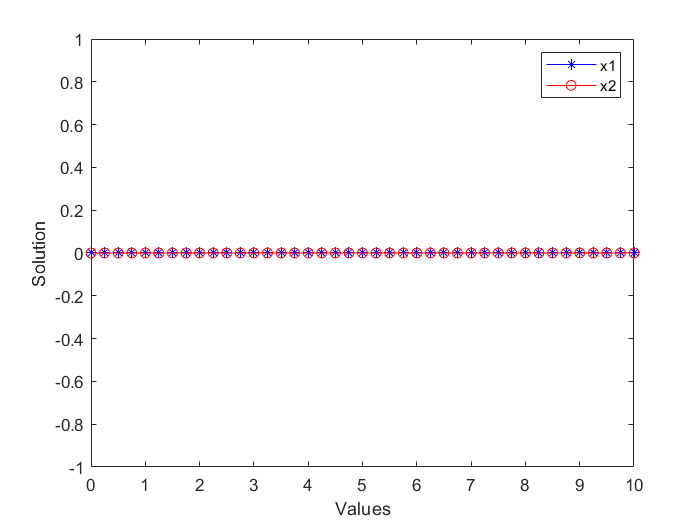


% Ploting
plot(t, x(:,1), 'b-*', t, x(:,2), 'r-o');
legend('x1', 'x2');
xlabel('Values');
ylabel('Solution');

### Q2: Find the solution of the system 

###                 
$$\begin{array}{l}
{x_1 }^{\prime } =x_2 \\
{x_2 }^{\prime } =-x_1 \\
x_1 \left(0\right)=x_2 \left(0\right)=1
\end{array}$$


#### 
$${\mathrm{Sol}}^n :$$


The solution for the system is given below: 

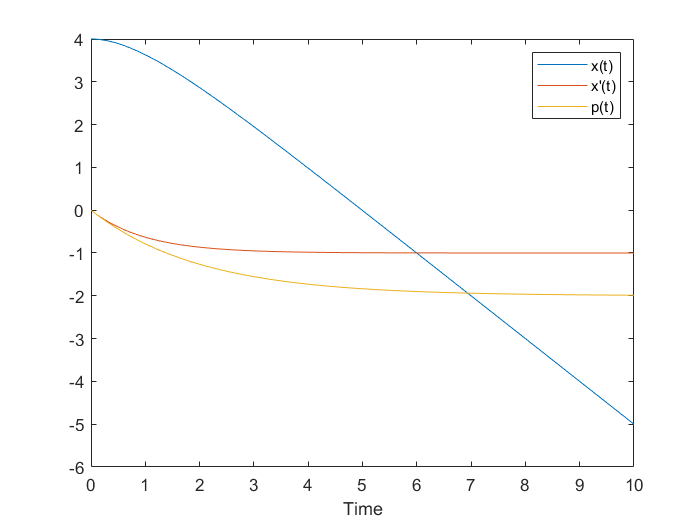

% Define the system of ODEs
% x'' + x' + x/y = 0
% p'=-1/2 * p - x/y ; 
%initial conditions
% x(0) = 4, p(0) = 0
%%

% Set the initial conditions
y0 = [4; 0 ;0];

% Set the time span
tspan = [0, 10];

% Call the ode45 function
[t, y] = ode45(@myode, tspan, y0);

% Extract x(t), x'(t), and p(t) from the solution
x = y(:,1);
xp = y(:,2);
p = y(:,3);

% Plot the solution
plot(t, x, t, xp, t, p);
legend('x(t)', 'x''(t)', 'p(t)');
xlabel('Time');

### Q3: Solve $\begin{array}{l}
y^{\prime } =-2\ldotp 3y\\
y\left(0\right)=0
\end{array}$

#### 
$${\mathrm{Sol}}^n :$$


The solution for the system is given below: 

clear all
% define the ODE
dydt = @(t, y) -2*3*y;

% define the initial condition
y0 = 0;

% define time span
tspan = [0 10];

% solving the ODE using ode45
[t y] = ode45(dydt, tspan, y0)

t =          0
    0.2500
    0.5000
    0.7500
    1.0000
    1.2500
    1.5000
    1.7500
    2.0000
    2.2500


y =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


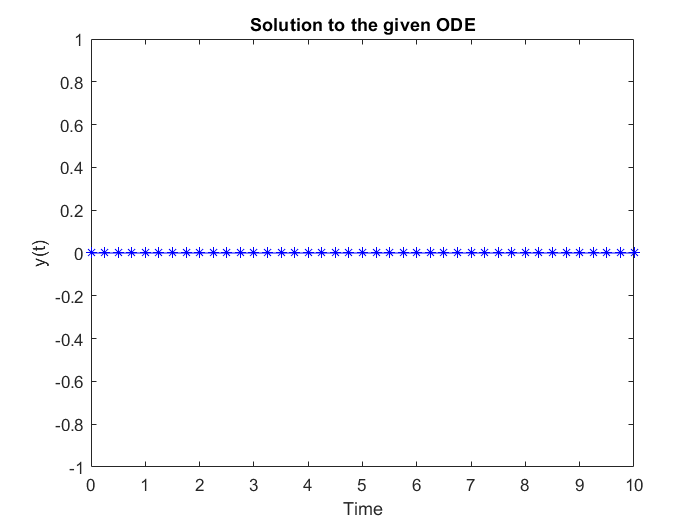


% plot the solution
plot(t, y, 'b-*')
xlabel('Time')
ylabel('y(t)')
title('Solution to the given ODE')

### Q4: Use ODE23 and ODE45 to solve

###             y' = y, y(0) = 1

### How many points are returned by ODE23 and ODE45?

#### 
$${\mathrm{Sol}}^n :$$


The solution for the system is given below: 

clear all
% define the system
% y' = y with y(0) = 1
dydt = @(t, y) y;

y0 = 1; % define initial condition
tspan = [0 10]; % time span

% solving the system using ode23
[t y] = ode23(dydt, tspan, y0);
fprintf('Total points returned by ode23: ');

Total points returned by ode23: 

total_pts_23 = length(t)

total_pts_23 = 36


% solving the system using ode45
[t y] = ode45(dydt, tspan, y0);
fprintf('Total points returned by ode45: ');

Total points returned by ode45: 

total_pt_45 = length(t)

total_pt_45 = 45

### Q5: Solve $y^{\prime } =-\mathrm{ty}+1,y\left(0\right)=1$

#### 
$${\mathrm{Sol}}^n :$$


The solution for the system is given below: 

clear all
% define the system
% y' = -t * y + 1 with y(0) = 1
dydt = @(t, y) -t * y + 1;

y0 = 1; % define initial condition
tspan = [0 10]; % time span

% solving the system using ode45
[t y] = ode45(dydt, tspan, y0)

t =          0
    0.0502
    0.1005
    0.1507
    0.2010
    0.4510
    0.7010
    0.9510
    1.2010
    1.3369


y =     1.0000
    1.0489
    1.0951
    1.1383
    1.1783
    1.3245
    1.3788
    1.3467
    1.2468
    1.1740


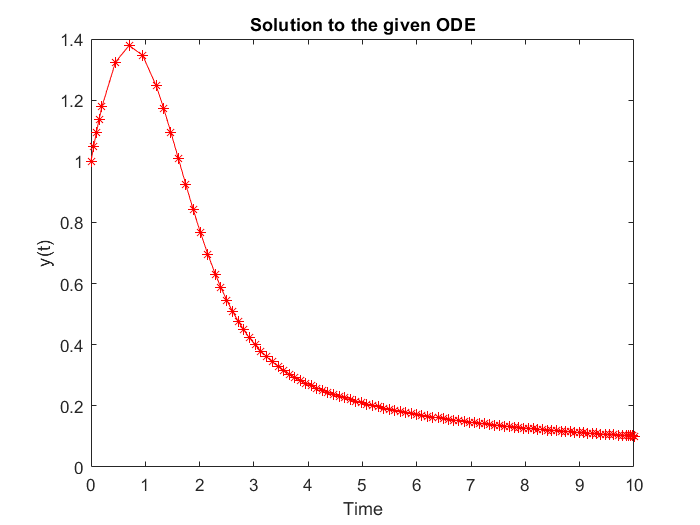


% plot the solution
plot(t, y, 'r-*')
xlabel('Time')
ylabel('y(t)')
title('Solution to the given ODE')

### Q6: Solve $y^{\prime } =t^2 y=0,y\left(0\right)=1\;\mathrm{for}\;0\le t\le 2$

### 
$${\mathrm{Sol}}^n :$$
  

The solution for the system is given below: 

clear all
% define the system
% y' = t^2 * y = 0 with y(0) = 1 for 0 <= t <= 2
dydt = @(t, y) t^2 * y + 1;

y0 = 1; % define initial condition
tspan = [0 2]; % time span

% solving the system using ode45
[t y] = ode45(dydt, tspan, y0)

t =          0
    0.0500
    0.1000
    0.1500
    0.2000
    0.2500
    0.3000
    0.3500
    0.4000
    0.4500


y =     1.0000
    1.0500
    1.1004
    1.1513
    1.2031
    1.2562
    1.3111
    1.3682
    1.4280
    1.4912


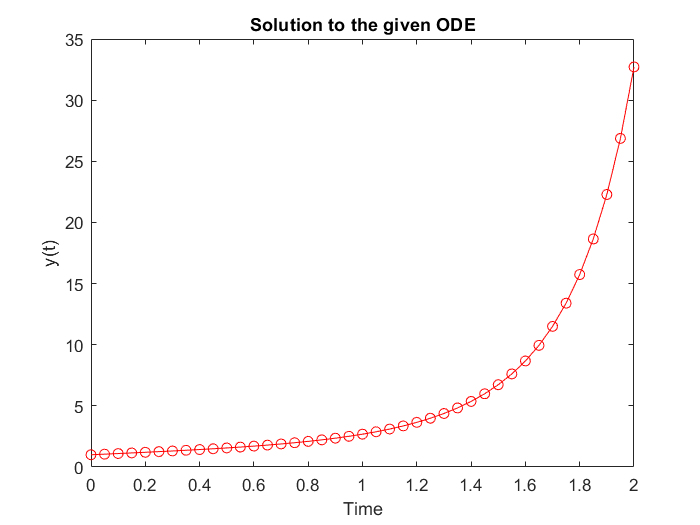


% plot the solution
plot(t, y, 'r-o')
xlabel('Time')
ylabel('y(t)')
title('Solution to the given ODE')

#### Q7: What numerical techniques are used by ode23 and ode45?

#### Ans: 

ode23 is a three-stage, third-order, Runge-Kutta method. ode45 is a six-stage, fifth-order, Runge-Kutta method.

### Q8: Solve $\frac{\mathrm{dy}}{\mathrm{dt}\;}=\frac{2}{\sqrt{1-t^2 }},-1<t<1,y\left(0\right)=1$

#### 
$${\mathrm{Sol}}^n :$$


The solution for the system is given below: 

clear all
% define the system
% dy/dt = 2 / sqrt(1-t^2) with y(0) = 1 for -1 < t < 1
dydt = @(t, y) 2 / sqrt(1 - t^2);

y0 = 1; % define initial condition
tspan = [-1 1]; % time span

% solving the system using ode45
[t y] = ode23(dydt, tspan, y0)

t =    -1.0000
   -1.0000
   -1.0000
   -1.0000
   -1.0000
   -1.0000
   -1.0000
   -1.0000
   -1.0000
   -1.0000


y =      1
   Inf
   Inf
   Inf
   Inf
   Inf
   Inf
   Inf
   Inf
   Inf


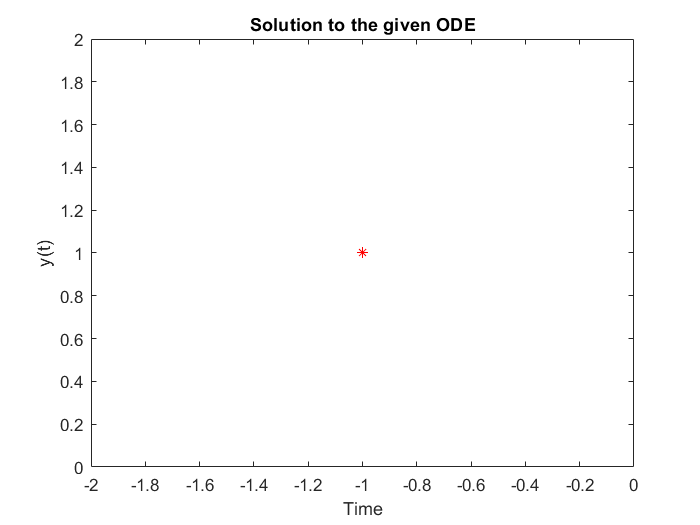


% plot the solution
plot(t, y, 'r-*')
xlabel('Time')
ylabel('y(t)')
title('Solution to the given ODE')

### Q9: Solve y'' - 2y' + y = exp(-t), y(0) = 2, y'(0) = 0

#### 
$${\mathrm{Sol}}^n :$$


The solution for the system is given below: 

To solve this second order ODE, at first we need to convert the system in to a first order ODE system by introducing a new variable $z=y^{\prime } :$


$$\begin{array}{l}
y^{\prime } =z\\
z^{\prime } =2z-y+\mathrm{exp}\left(-t\right)
\end{array}$$


The inital conditions become: 


$$\begin{array}{l}
y\left(0\right)=2\\
z\left(0\right)=y^{\prime } \left(0\right)=0
\end{array}$$


Code for generating a phase portrait for the solution along with the solution:

clear all
% define the system
% y'' - 2y' + y = exp(-t) with y(0) = 2, y'(0) = 0
dydt = @(t, y) [y(2); 2*y(2) - y(1) + exp(-t)];
y0 = [2; 0]; % define initial conditions
tspan = [0 10]; % time span

% solving the system using ode45
[t y] = ode45(dydt, tspan, y0)

t =          0
    0.0001
    0.0001
    0.0002
    0.0002
    0.0005
    0.0007
    0.0010
    0.0012
    0.0025


y = 	1.0e+05 *

    0.0000         0
    0.0000   -0.0000
    0.0000   -0.0000
    0.0000   -0.0000
    0.0000   -0.0000
    0.0000   -0.0000
    0.0000   -0.0000
    0.0000   -0.0000
    0.0000   -0.0000
    0.0000   -0.0000


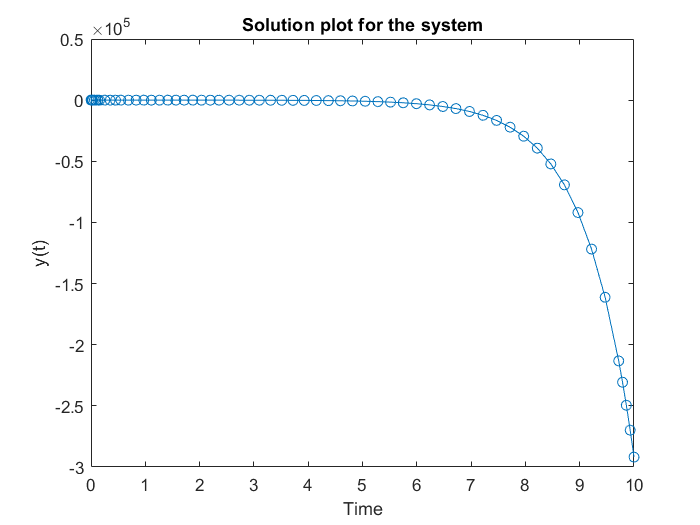


% plot the solution
plot(t, y(:, 1), '-o')
xlabel('Time')
ylabel('y(t)')
title('Solution plot for the system')

#### Q10: Generate a phase protrait for the system in problem 9.

#### 
$${\mathrm{Sol}}^n :$$


The phase can be portraited in a phase space $\left(y,y^{\prime } \right)$:

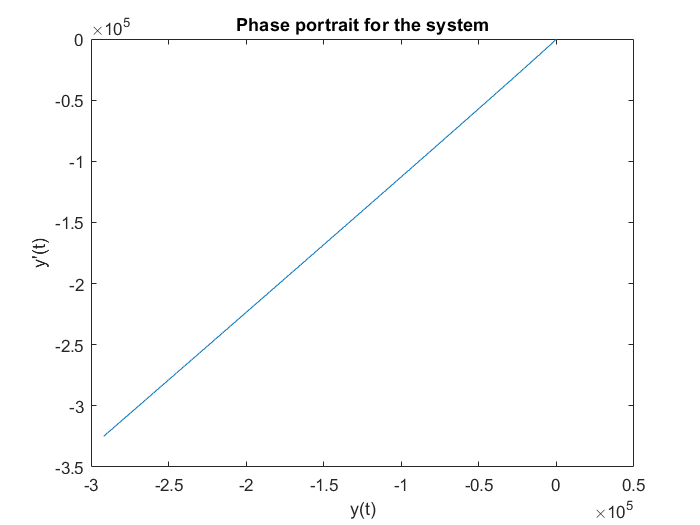

clear all
% define the system
% y'' - 2y' + y = exp(-t) with y(0) = 2, y'(0) = 0
dydt = @(t, y) [y(2); 2*y(2) - y(1) + exp(-t)];
y0 = [2; 0]; % define initial conditions
tspan = [0 10]; % time span

% solving the system using ode45
[t y] = ode45(dydt, tspan, y0);

% plot the solution
plot(y(:, 1), y(:, 2))
xlabel('y(t)')
ylabel("y'(t)")
title('Phase portrait for the system')

### ***Q***11: Use MATLAB to show that $y=2\mathrm{sin}\;t-3\mathrm{cos}\;t$ does not satisfy ${y^{\prime } }^{\prime } -11y=4\mathrm{cos}\;t$.

#### 
$${\mathrm{Sol}}^n :\;$$


% define the equation
syms t
y = 2 * sin(t) - 3 * cos(t);
d1y = diff(y);
d2y = diff(y, 2);
if simplify(d2y - 11*y) == 4 * cos(6*t)
    fprintf('Satisfied!!!\n');
else
    fprintf('Does not satisfy!!!\n');
end

Does not satisfy!!!


function dy = myode(~, y)
    y1 = y(1);
    y2 = y(2);
    y3 = y(3);
    dy = [y2; -y2 - y1/y1(1); -1/2*y3 - y1/y1(1)];
end

# The End